# 5 | DATA MANIPULATION

Jay Klopper MD MMed(Surgery)Cum Laude

The George Washington University

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 12-Jun-2024 13:49:58

## Set up the Import Options and import the data

clear global
opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet and range
opts.Sheet = "heart";
opts.DataRange = "A2:L919";

% Specify column names and types
opts.VariableNames = ["Age", "Sex", "ChestPainType", "RestingBP", "Cholesterol", "FastingBS", "RestingECG", "MaxHR", "ExerciseAngina", "Oldpeak", "ST_Slope", "HeartDisease"];
opts.VariableTypes = ["double", "categorical", "categorical", "double", "double", "double", "categorical", "double", "categorical", "double", "categorical", "categorical"];

% Specify variable properties
opts = setvaropts(opts, ["Sex", "ChestPainType", "RestingECG", "ExerciseAngina", "ST_Slope", "HeartDisease"], "EmptyFieldRule", "auto");

% Import the data
heart = readtable("/Users/juanheinklopper/Documents/MATLAB/MATLAB for Data Science/Data/heart.xlsx", opts, "UseExcel", false)

heart = 918×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N     

clear opts

## Introduction

As in the previous chapter, we used the built-in MATLAB functionality to import a spreadsheet file.

In this chapter we continue our exploration of exploratory data analysis by manipulating the data that we import.

## Using indexing to select data

Filtering for only parts of our data for analysis is a very common task in data science. We explored indexing of vectors and matrices in chapter 2. We can apply the same principles to `table` objects. Below, we filter only for the first row (all columns) by using indexing. The colon symbol `:` is shorthand for indicating that we want all (in this cases all the columns). Remember that indexing is in the form *row, column*.

% Show the data for the first subject
heart(1,:)

ans = 1×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N              0          Up            0      


The `head` function is used to display the first $n$ rows of data. Below, we view the first $5$ rows.

% Show the data for the first 5 subjects
head(heart,5)

    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N               1        Fl

The `tail` function return the last rows.

% Show data for last 5 subjects
tail(heart,5)

    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    45      M          TA             110           264            0          Normal       132           N             1.2        Flat           1      
    68      M          ASY            144           193            1          Normal       141           N             3.4        Fl

Next we filter for rows $1$ and $3$ and all the columns.

% Show rows 1 and 3
heart([1 3],:)

ans = 2×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N              0          Up            0      
    37      M          ATA            130           283            0          ST            98           N         

We can use the names of the columns instead of their indices. The names of the columns are passed as a cell array.

% Select only the Age and Sex variables
heart(:,{'Age','Sex'})

ans = 918×2 table
    Age    Sex
    ___    ___

    40      M 
    49      F 
    37      M 
    48      F 
    54      M 
    39      M 
    45      F 
    54      M 
    37      M 
    48      F 
    37      F 
    58      M 
    39      M 
    49      M 
    42      F 
    54      F 


## Data filtering by condition

Other than indexing, we can also filter by condition. A condition returns either a true or a false value. We use this fact to return only observations that return as value of true. Below, we return only observations (with all columns selected) by filtering the `Age` column for values in excess of $50$.

% Filter only those older than 50
heart(heart.Age > 50,:)

ans = 602×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    54      M          NAP            150           195            0          Normal       122           N               0        Up             0      
    54      M          ATA            110           208            0          Normal       142           N       

Next we filter only for females (encoded as `F` in the `Sex` column).

% Filter only female subjects
heart(heart.Sex == "F",:)

ans = 193×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    49      F          NAP            160           180            0          Normal       156           N               1        Flat           1      
    48      F          ASY            138           214            0          Normal       108           Y       

Filtering on more than one condition is achieved using logical and. The symbol for this is `&`. Below we filter for all subjects older than $50$ who are female. Note that both conditions must be met.

% Filter females older than 50
heart(heart.Age > 50 & heart.Sex == "F",:)

ans = 115×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    54      F          ATA            120           273            0          Normal       150           N             1.5        Flat           0      
    53      F          ATA            113           468            0          Normal       127           N       

Using logical or to filter values whenever any condition is met. Below we filter for subjects older than $50$ or who are female, using the `|` symbol. We need only one of the condition to be true for inclusion in the filtering.

% Filter females or those older than 50
heart(heart.Age > 50 | heart.Sex == "F",:)

ans = 680×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    49      F          NAP            160           180            0          Normal       156           N               1        Flat           1      
    48      F          ASY            138           214            0          Normal       108           Y       

## Change variable names

It is often required to rename variables. The `renamevars` function is used to achieve this. Below we change the `RestingECG` column name to the `Resting_ECG`.

% Change RestingECG to Resting_ECG
heart = renamevars(heart,["RestingECG"],["Resting_ECG"])

heart = 918×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    Resting_ECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    ___________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal        172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal        156           N 

## Add new column based on values of another

Adding new column is a task that is often required in data science. We can add any values to a new column. It is most useful, though, to base the values on calculations performed on the values in other columns. Below, we convert the units of the `Cholesterol` column to mmol/L. We also use the `round` function to round off the calculated values to two decimal places.

% Add a new column named Cholesterol_mmol
heart.Cholesterol_mmol = round(heart.Cholesterol ./ 38.67,2)

heart = 918×13 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol
    ___    ___    _____________    _________    ___________    _________    _______    _____    ______________    _______    ________    ____________    ________________

    40      M          ATA            140           289            0        Normal      172           N               0        Up             0                7.47      
    49      F          NAP

## Change the values of observations in a column based on conditions

The values in a new column can also be created based on conditions applied to the values of another column. Below we add a new column called `HeartDiseaseClass` and assign the values of the `HeartDisease` column to the new column.

% Add a new column called HeartDiseaseClass as a copy of the HeartDisease
% variable
heart.HeartDiseaseClass = heart.HeartDisease

heart = 918×14 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol    HeartDiseaseClass
    ___    ___    _____________    _________    ___________    _________    _______    _____    ______________    _______    ________    ____________    ________________    _________________

    40      M          ATA            140           289            0        Normal      172           N               0 

Next, we use the `ismember` function to filter for rows with a $0$ in the new `HeartDisease` class and replace them with the value `No`.

% Change the values in the new column to "No" if the value is 0
heart.HeartDiseaseClass(ismember(heart.HeartDiseaseClass, ["0"])) = "No"

heart = 918×14 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol    HeartDiseaseClass
    ___    ___    _____________    _________    ___________    _________    _______    _____    ______________    _______    ________    ____________    ________________    _________________

    40      M          ATA            140           289            0        Normal      172           N               0 

We do the same for those with heart disease.

% Change the values in the new column to "Yes" if the value is 1
heart.HeartDiseaseClass(ismember(heart.HeartDiseaseClass, ["1"])) = "Yes"

heart = 918×14 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol    HeartDiseaseClass
    ___    ___    _____________    _________    ___________    _________    _______    _____    ______________    _______    ________    ____________    ________________    _________________

    40      M          ATA            140           289            0        Normal      172           N               0 

## Change numerical variable to nominal variable

Categorizing a numerical variable is another common task in data science. Below, we create three classes based on the `Age` column by using the `discretize` function and setting the intervals as left-closed right-open intervals.

% Add a new column to the data table called AgeClass
% Let observation be "Group A" if Age observation is in interval [0,50)
% Let observation be "Group B" if Age observation is in interval [50,75)
% Let observation be "Group C" if Age observation is in interval [75,100)
heart.AgeClass = discretize(heart.Age, [0 50 75 100], 'categorical', ["Group A", "Group B", "Group C"])

heart = 918×15 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease    Cholesterol_mmol    HeartDiseaseClass    AgeClass
    ___    ___    _____________    _________    ___________    _________    _______    _____    ______________    _______    ________    ____________    ________________    _________________    ________

    40      M          ATA            140           289       

## Working with dates and times

Working with dates and times is essential and sometimes very difficult. Most difficulty stems from the data capture in a spreadsheet of database file. The problems that we face with dates and times can be avoided by proper data capture in a consistent format and not using formatting built into spreadsheet and database programs. In this section, we use MATLAB to generate dates and times.

% Add day as a string
datetime('June 18, 2024')

ans = datetime
   18-Jun-2024


% Current day and time
dt = datetime("now")

dt = datetime
   18-Jun-2024 14:07:24


% Year
year(dt)

ans = 2024

dt.Year

ans = 2024

% Month number
month(dt)

ans = 6

%Month name
month(dt,'name')

ans = 1×1 cell array
    {'June'}


% Day
day(dt)

ans = 18

% Day of the week
day(dt,'dayofweek')

ans = 3

% Long day name
day(dt,'name')

ans = 1×1 cell array
    {'Tuesday'}


[y,m,d] = ymd(dt)

y = 2024

m = 6

d = 18

years = randi(24,20,1) + 2000

years =         2005
        2021
        2015
        2009
        2006
        2006
        2013
        2011
        2018
        2002


months = randi(12,20,1)

months =     10
     6
     1
     8
     3
     9
     7
     4
    12
    10


days = randi(28,20,1)

days =     19
    15
     9
    20
    11
    16
    25
    24
    26
    27


dates = datetime([years months days],"Format","uuuu-MM-dd")

dates = 20×1 datetime array
   2005-10-19
   2021-06-15
   2015-01-09
   2009-08-20
   2006-03-11
   2006-09-16
   2013-07-25
   2011-04-24
   2018-12-26
   2002-10-27
   2021-11-23
   2017-01-01
   2004-03-01
   2021-09-03
   2005-09-08
   2015-10-01
   2014-07-12
   2004-06-10
   2001-08-16
   2019-11-26


day(dates,'name')

ans = 20×1 cell array
    {'Wednesday'}
    {'Tuesday'  }
    {'Friday'   }
    {'Thursday' }
    {'Saturday' }
    {'Saturday' }
    {'Thursday' }
    {'Sunday'   }
    {'Wednesday'}
    {'Sunday'   }
    {'Tuesday'  }
    {'Sunday'   }
    {'Monday'   }
    {'Friday'   }
    {'Thursday' }
    {'Thursday' }
    {'Saturday' }
    {'Thursday' }
    {'Thursday' }
    {'Tuesday'  }


% Create a logical array to hold all the weekend dates
idx = isweekend(dates)

idx = 20×1 logical array
   0
   0
   0
   0
   1
   1
   0
   1
   0
   1


% Display the weekend dates
dates(idx)

ans = 6×1 datetime array
   2006-03-11
   2006-09-16
   2011-04-24
   2002-10-27
   2017-01-01
   2014-07-12


Next we import a spreadsheet file that contains a date column. This is done from the HOME tab.

% Call file from Workspace
DateData

DateData = 125×2 table
      Date      Patients
    ________    ________

    01/07/45       23   
    01/29/45       15   
    01/14/45       32   
    01/22/45       19   
    01/16/45       22   
    01/29/45       25   
    01/12/45       22   
    01/09/45       16   
    01/27/45       23   
    01/15/45       18   
    02/01/45       24   
    02/13/45       14   
    02/17/45       17   
    02/22/45       15   
    02/11/45       28   
    02/13/45       17   


% Compute group summary
frequencyTable = groupsummary(DateData,"Date","monthname")

frequencyTable = 12×2 table
    monthname_Date    GroupCount
    ______________    __________

      January             10    
      February            10    
      March               16    
      April                5    
      May                 13    
      June                 8    
      July                 9    
      August               8    
      September           18    
      October             12    
      November             8    
      December             8    


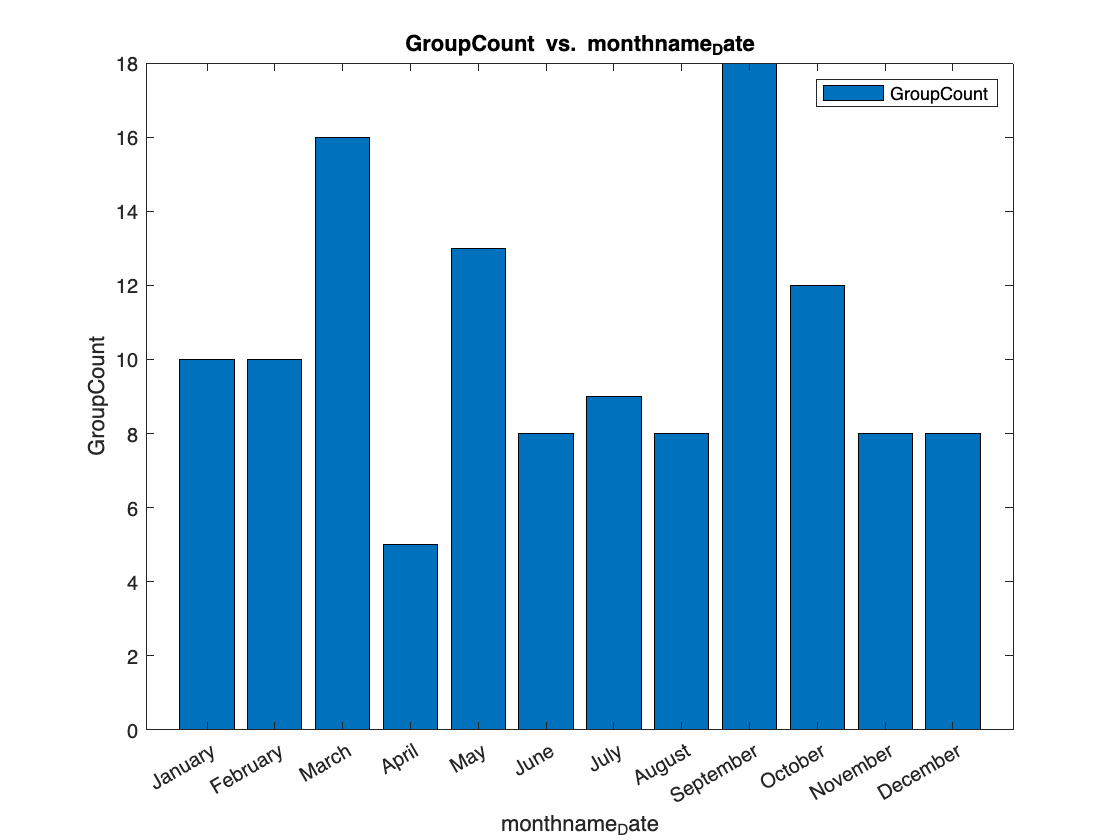

% Create bar of selected data
h3 = bar(frequencyTable.monthname_Date,frequencyTable.GroupCount,"DisplayName","GroupCount");

% Add xlabel, ylabel, title, and legend
xlabel("monthname_Date")
ylabel("GroupCount")
title("GroupCount vs. monthname_Date")
legend

## Missing data

Missing data can occur commonly in data sets. Missing data refers to the absence of data points or values in a dataset where they were expected or should have been recorded. This can occur for various reasons such as non-response in surveys, data collection errors, or loss of data during storage. There are different types of missingness.

1. **Missing Completely at Random (MCAR)**: Missing data is considered MCAR if the probability of a data point being missing is completely independent of any observed or unobserved data in the dataset. In other words, the missingness is unrelated to the values of any variables. For instance, if survey responses are missing purely due to random technical errors, the data is MCAR

2. **Missing at Random (MAR)**: Missing data is considered MAR if the probability of a data point being missing is related to some of the observed data but not the missing data itself. That means the missingness can be explained by other measured variables in the dataset. For example, if older individuals are less likely to answer a particular survey question, but this tendency is consistent across all questions, the data is MAR if age information is recorded

3. **Missing Not at Random (MNAR)**: Missing data is considered MNAR if the probability of a data point being missing is related to the value of the missing data itself. This means that the missingness is systematically related to the unobserved value. For instance, if people with higher incomes are less likely to report their income, the data is MNAR.

In this section we only explore the use of the Clean Missing Data app. First we note that the `nan` keyword, which is short for not a number is used to indicate missing data.

% Use the nan keyword
nan

ans = NaN

We create a column vector of random integers and then overwrite the values at indices $3,11$, and $14$ with the `nan` keyword.

% Create a column vector of 20 random integers assigned to the variable
% array
array = randi(10,20,1)+20

array =     28
    27
    30
    28
    27
    30
    21
    23
    30
    28


% Overwrite observations 3, 11, and 14 with missing data
array([3 11 14]) = nan

array =     28
    27
   NaN
    28
    27
    30
    21
    23
    30
    28


We cannot calculate statistics such as the mean with this vector as the values held at indices $3, 11$, and $14$ are unknown.

% Calculate the mean
mean(array)

ans = NaN

The simplest task is to remove observations with missing data. This might be a problem when there are many missing observations. Instead, the Clean Missing Data app can be used to impute the missing data.

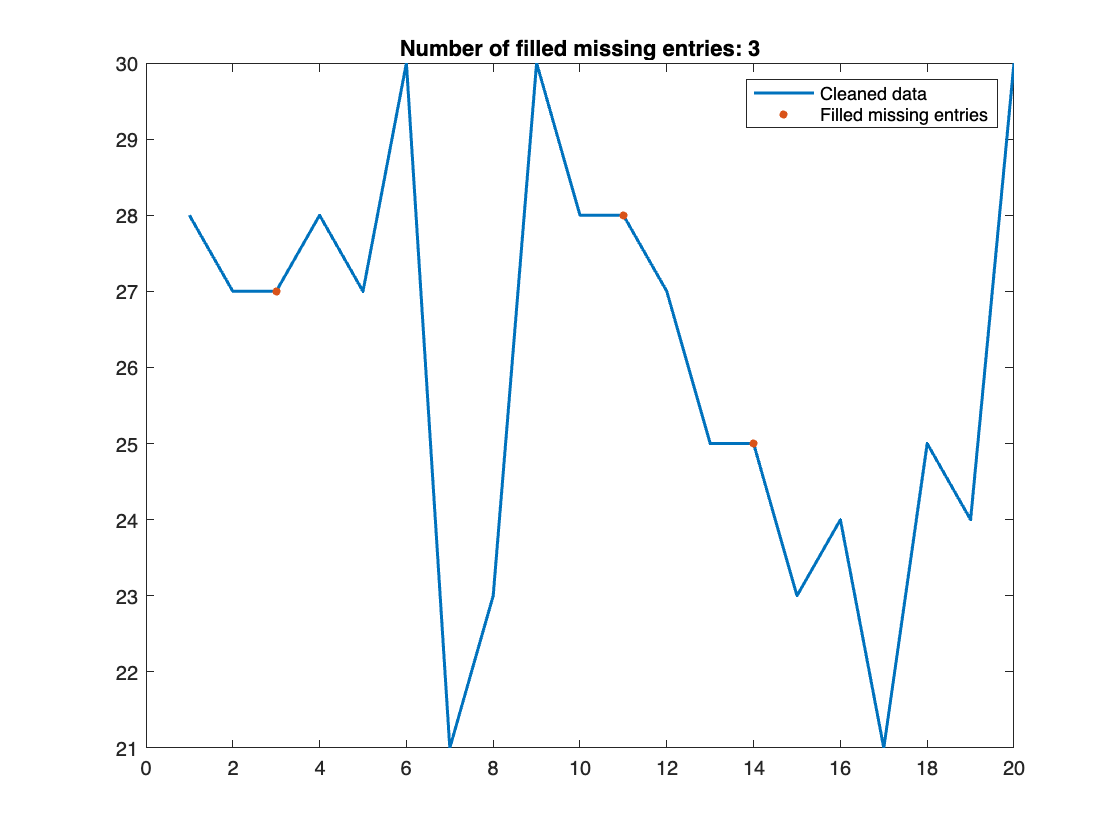

% Fill missing data
[cleanedArray,missingIndices] = fillmissing(array,"previous");

% Display results
figure

% Plot cleaned data
plot(cleanedArray,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices),cleanedArray(missingIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))

hold off
legend

clear missingIndices

The mean can now be calculated.

% Calculate the mean
mean(cleanedArray)

ans = 26.0500